Code to find Tau values: 

%naming convention for step inputs -- in volts, data_ab = step input of a.b
%volts
data_n5 = load("step_input_-5.mat","Y","U","T");
data_n4 = load("step_input_-4.mat","Y","U","T");
data_n3 = load("step_input_-3.mat","Y","U","T");
data_n2 = load("step_input_-2.mat","Y","U","T");
data_n1 = load("step_input_-1.mat","Y","U","T");
data_p1 = load("step_input_1.mat","Y","U","T");
data_p2 = load("step_input_2.mat","Y","U","T");
data_p3 = load("step_input_3.mat","Y","U","T");
data_p4 = load("step_input_4.mat","Y","U","T");
data_p5 = load("step_input_5.mat","Y","U","T");

data_array = [data_n5, data_n4, data_n3, data_n2, data_n1, data_p1, data_p2, data_p3, data_p4, data_p5]

data_array = 1×10 struct array with fields:
    Y
    U
    T


Step_Inputs = [-5 -4 -3 -2 -1 1 2 3 4 5]'

Step_Inputs =     -5
    -4
    -3
    -2
    -1
     1
     2
     3
     4
     5


tau_array = [0 0 0 0 0 0 0 0 0 0]

tau_array =      0     0     0     0     0     0     0     0     0     0


k_array = [0 0 0 0 0 0 0 0 0 0]

k_array =      0     0     0     0     0     0     0     0     0     0




for i = 1:10
    tau_array(i) = get_tau(data_array(i).Y, data_array(i).T, data_array(i).U)
    k_array(i) = get_k(data_array(i).Y, data_array(i).T, data_array(i).U)
end

threshold = 0.6983

tau = 0

Estimated Time Constant (tau): 0 seconds


tau_array =      0     0     0     0     0     0     0     0     0     0


Calculated Gain (K): 0.65117


k_array =     0.6512         0         0         0         0         0         0         0         0         0


threshold = 2.6112

tau = 0

Estimated Time Constant (tau): 0 seconds


tau_array =      0     0     0     0     0     0     0     0     0     0


Calculated Gain (K): 0.12509


k_array =     0.6512    0.1251         0         0         0         0         0         0         0         0


threshold = 1.8268

tau = 0.2900

Estimated Time Constant (tau): 0.29 seconds


tau_array =          0         0    0.2900         0         0         0         0         0         0         0


Calculated Gain (K): -0.77522


k_array =     0.6512    0.1251   -0.7752         0         0         0         0         0         0         0


threshold = 0.5907

tau = 0

Estimated Time Constant (tau): 0 seconds


tau_array =          0         0    0.2900         0         0         0         0         0         0         0


Calculated Gain (K): 0.50428


k_array =     0.6512    0.1251   -0.7752    0.5043         0         0         0         0         0         0


threshold = 0.4463

tau = 0.7560

Estimated Time Constant (tau): 0.756 seconds


tau_array =          0         0    0.2900         0    0.7560         0         0         0         0         0


Calculated Gain (K): -1.9942


k_array =     0.6512    0.1251   -0.7752    0.5043   -1.9942         0         0         0         0         0


threshold = -0.4474

tau = 1.0000e-03

Estimated Time Constant (tau): 0.001 seconds


tau_array =          0         0    0.2900         0    0.7560    0.0010         0         0         0         0


Calculated Gain (K): -2.154


k_array =     0.6512    0.1251   -0.7752    0.5043   -1.9942   -2.1540         0         0         0         0


threshold = -1.0928

tau = 0.5380

Estimated Time Constant (tau): 0.538 seconds


tau_array =          0         0    0.2900         0    0.7560    0.0010    0.5380         0         0         0


Calculated Gain (K): 0.20874


k_array =     0.6512    0.1251   -0.7752    0.5043   -1.9942   -2.1540    0.2087         0         0         0


threshold = 1.3255

tau = 0.4000

Estimated Time Constant (tau): 0.4 seconds


tau_array =          0         0    0.2900         0    0.7560    0.0010    0.5380    0.4000         0         0


Calculated Gain (K): 1.2866


k_array =     0.6512    0.1251   -0.7752    0.5043   -1.9942   -2.1540    0.2087    1.2866         0         0


threshold = 1.3769

tau = 0

Estimated Time Constant (tau): 0 seconds


tau_array =          0         0    0.2900         0    0.7560    0.0010    0.5380    0.4000         0         0


Calculated Gain (K): -0.4382


k_array =     0.6512    0.1251   -0.7752    0.5043   -1.9942   -2.1540    0.2087    1.2866   -0.4382         0


threshold = 0.7642

tau = 0

Estimated Time Constant (tau): 0 seconds


tau_array =          0         0    0.2900         0    0.7560    0.0010    0.5380    0.4000         0         0


Calculated Gain (K): -0.58061


k_array =     0.6512    0.1251   -0.7752    0.5043   -1.9942   -2.1540    0.2087    1.2866   -0.4382   -0.5806


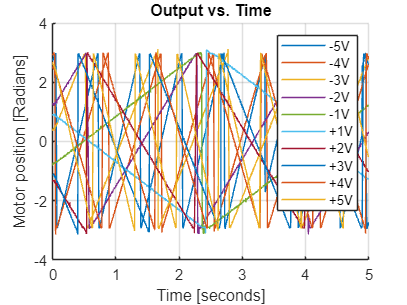


figure;
hold on; 
for i = 1:10
    plot(data_array(i).T, data_array(i).Y); 
end 

grid on;
title('Output vs. Time');
ylabel('Motor position [Radians]'); 
xlabel('Time [seconds]');
legend('-5V', '-4V', '-3V', '-2V', '-1V', ...
     '+1V', '+2V', '+3V', '+4V', '+5V')

hold off;

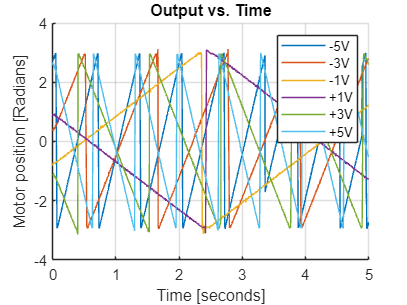


figure;
hold on; %356L code skipped a few, so will I
plot(data_array(1).T, data_array(1).Y); 
plot(data_array(3).T, data_array(3).Y); 
plot(data_array(5).T, data_array(5).Y); 
plot(data_array(6).T, data_array(6).Y); 
plot(data_array(8).T, data_array(8).Y); 
plot(data_array(10).T, data_array(10).Y); 

grid on;
title('Output vs. Time');
ylabel('Motor position [Radians]'); 
xlabel('Time [seconds]');
legend('-5V', '-3V', '-1V', '+1V', '+3V','+5V')
    
hold off;


disp('Plotting complete.');

Plotting complete.



Tau = tau_array';
K = k_array';
data = table(Step_Inputs, Tau, K);

k_linear_range = [k_array(6:10)];
tau_linear_range = [tau_array(6:10)];

model_k = mean(k_linear_range);
model_tau = mean(tau_linear_range);

[break]

s = tf('s');
P = model_k/(model_tau*s+1)

P =
 
    -0.3355
  ------------
  0.1878 s + 1
 
Continuous-time transfer function.
Model Properties


model_pole = pole(P)

model_pole = -5.3248

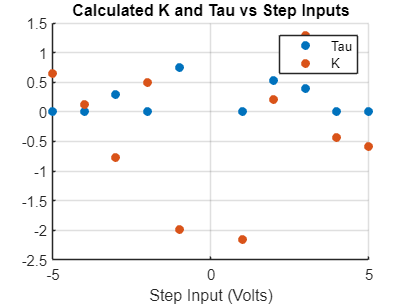


figure;
hold on;
scatter(Step_Inputs, tau_array,"filled")
scatter(Step_Inputs, k_array,"filled")
grid on;    
title('Calculated K and Tau vs Step Inputs');
xlabel('Step Input (Volts)');
legend("Tau", "K");
hold off

function[tau] = get_tau(Y, T, U)

final_value = mean(Y(end-50:end)); % Steady-state value (assuming system settled)
initial_value = Y(1);
threshold = 0.632 * (final_value-initial_value) + initial_value

index = find(Y >= threshold, 1); % Find index where Y crosses threshold
tau = T(index)

disp(['Estimated Time Constant (tau): ', num2str(tau), ' seconds']);

end

function[k] = get_k(Y, T, U)

k = (mean(Y(end-50:end)) - Y(1)) / U(1);
disp(['Calculated Gain (K): ', num2str(k)]);
end